Direct Radian Power Match

solarIntensity=1000 %Watts per meter squared

solarIntensity = 1000

deviceArea=20.^2*10^-6 %ITO substrated, meter squared

deviceArea = 4.0000e-04

ledWavelength=450; %nanometers
wavelengthEnergy=6.62607015e-34*299792458/(ledWavelength*1e-9); %Joules
ppfEfficacy=2.73; %uMol/s/Watts
ppfEnergyEfficacy=ppfEfficacy*1e-6*6.022*1e23*wavelengthEnergy; % Watts(Radiant)/Watts(Electrical)
electricalNeed=solarIntensity*deviceArea/ppfEnergyEfficacy

electricalNeed = 0.5512

High Energy Photon Count Match

numPhoton=4.16e20; % Number of photons per meter squared <500nm
photonNumEfficacy=ppfEfficacy*1e-6*6.022*1e23;
electricalNeed=numPhoton*deviceArea/photonNumEfficacy

electricalNeed = 0.1012

LED Characteristics

dat=importdata("led_spread.csv");
degrees=dat.data(:,1);
npower=dat.data(:,2);

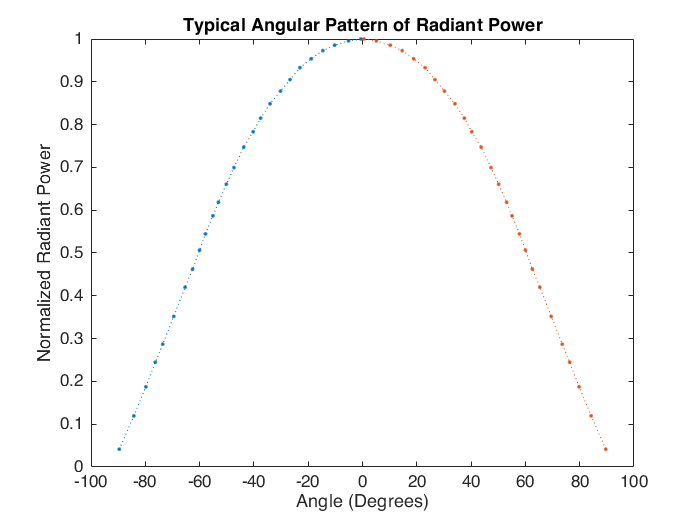

figure 
plot([-1*flip(degrees) degrees],[flip(npower) npower],'.:')
title('Typical Angular Pattern of Radiant Power')
xlabel('Angle (Degrees)')
ylabel('Normalized Radiant Power')

sumarea=2*trapz(degrees,npower);

sum10degree=2*trapz(degrees(1:2),npower(1:2));

sum10degree/sumarea

ans = 0.0790

accum_power=zeros(length(degrees)-1,1);
for i=1:length(degrees)-1
    accum_power(i,1)=2*trapz(degrees(1:i+1),npower(1:i+1));
end

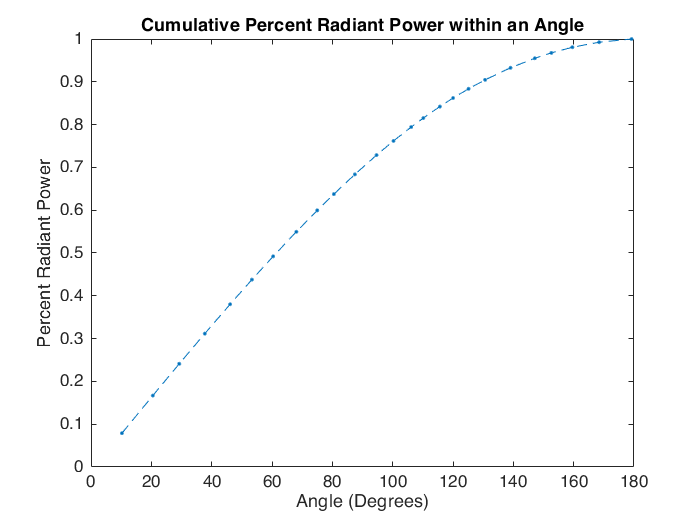

figure
plot(2*degrees(2:end),accum_power/sumarea,".--")
title('Cumulative Percent Radiant Power within an Angle')
xlabel('Angle (Degrees)')
ylabel('Percent Radiant Power')

Power vs Current

IVdat=importdata("led_IvsV.csv");
I=IVdat.data(:,1);
V=IVdat.data(:,2);

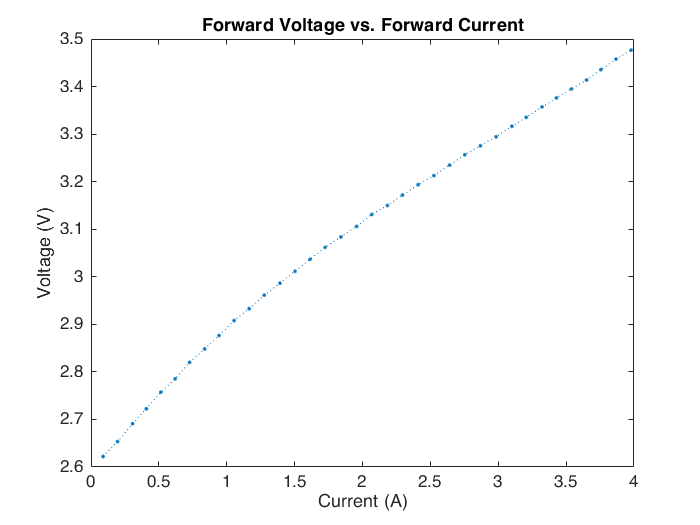

figure
plot(I,V,'.:')
title('Forward Voltage vs. Forward Current')
xlabel('Current (A)')
ylabel('Voltage (V)')

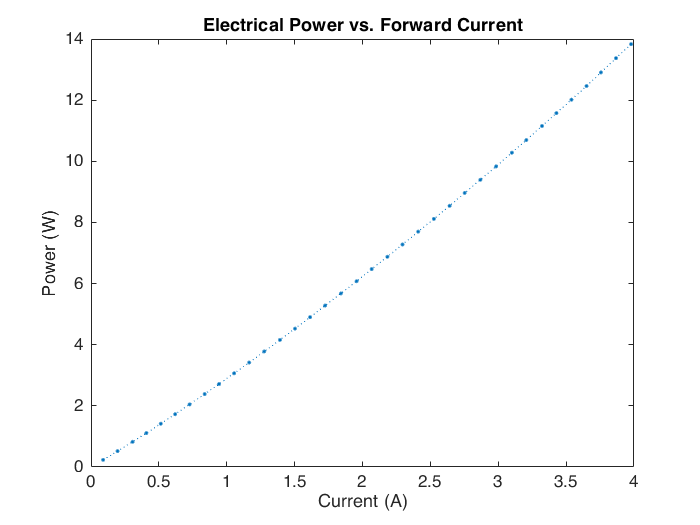

figure
plot(I,V.*I,'.:')
title('Electrical Power vs. Forward Current')
xlabel('Current (A)')
ylabel('Power (W)')

Relative Output Flux vs Current

fluxdat=importdata('led_FluxvsI.csv');
Iflux=fluxdat.data(:,1);
flux=fluxdat.data(:,2);

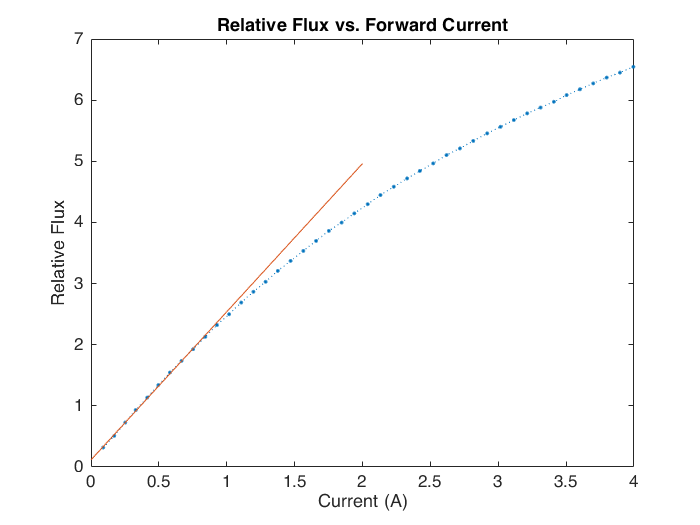

figure
plot(Iflux,flux,'.:')
title('Relative Flux vs. Forward Current')
xlabel('Current (A)')
ylabel('Relative Flux')
[r,m,b]=regression(Iflux(1:10),flux(1:10),'one');
hold on
x=0:0.01:2;
y=m*x+b;
plot(x,y)
hold off

10*cotd(26.67)

ans = 19.9087